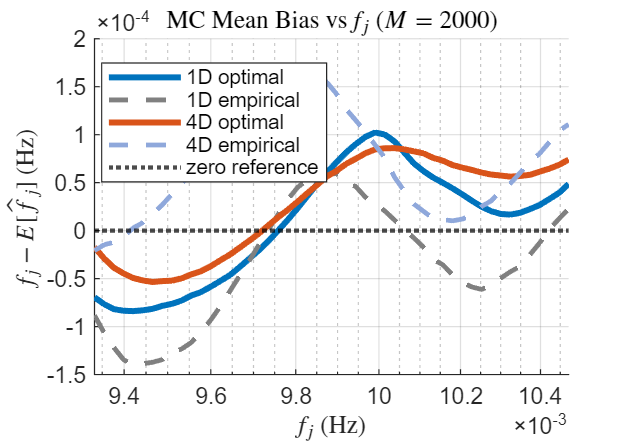

%% ===============================================================
%  Monte Carlo Reliability Analysis
%  - Figure 3: MC mean bias vs f_j
%  - Figure 4: Variance of estimated frequency vs f_j
% ===============================================================

clear; clc; close all;

%% =========================
% 0. Random seed control
% =========================
rand('seed',7);

%% =========================
% 1. Parameters
% =========================
M = 2000;              % debug先用5,100，最终改成2000
sigma_min = 1.0;
sigma_max = 2.0;

num_fj = 50;
fj_vals = logspace(-2.03, -1.98, num_fj)';

% --- SR parameters ---
params_1d_emp = [1, 1];
params_1d_opt = [0.09, 0.01];

params_4d_emp = [18, -10, 5, -3, 3, -5, 80, 15];
params_4d_opt = [18.70, -8.63, 6.63, -0.04, 7.87, -5.79, 80.54, 11.85];

%% =========================
% 2. Storage allocation
% =========================
% MC mean of estimated frequency: E[\hat{f}_j]
Efhat_1d_emp = zeros(num_fj,1);
Efhat_1d_opt = zeros(num_fj,1);
Efhat_4d_emp = zeros(num_fj,1);
Efhat_4d_opt = zeros(num_fj,1);

% Figure 3: MC mean bias = f_j - E[\hat{f}_j]
MCBias_1d_emp = zeros(num_fj,1);
MCBias_1d_opt = zeros(num_fj,1);
MCBias_4d_emp = zeros(num_fj,1);
MCBias_4d_opt = zeros(num_fj,1);
% 
% % Figure 4: variance
% Var_1d_emp = zeros(num_fj,1);
% Var_1d_opt = zeros(num_fj,1);
% Var_4d_emp = zeros(num_fj,1);
% Var_4d_opt = zeros(num_fj,1);

%% =========================
% 3. Progress bar
% =========================
h = waitbar(0,'Monte Carlo reliability analysis...');
total_steps = num_fj * M;
step = 0;

%% =========================
% 4. Monte Carlo loop
% =========================
for j = 1:num_fj

    fj = fj_vals(j);

    % Storage for M estimated frequencies at current f_j
    fhat_1d_emp = zeros(M,1);
    fhat_1d_opt = zeros(M,1);
    fhat_4d_emp = zeros(M,1);
    fhat_4d_opt = zeros(M,1);

    for m = 1:M

        % Random sigma perturbation
        sigma_m = sigma_min + (sigma_max - sigma_min) * rand;

        %M次实验：
        % 1D empirical
        [~,~,fhat_1d_emp(m)] = sr1d_eval_random(params_1d_emp, fj, sigma_m);

        % 1D optimal
        [~,~,fhat_1d_opt(m)] = sr1d_eval_random(params_1d_opt, fj, sigma_m);

        % 4D empirical
        [~,~,fhat_4d_emp(m)] = sr4d_eval_random(params_4d_emp, fj, sigma_m);

        % 4D optimal
        [~,~,fhat_4d_opt(m)] = sr4d_eval_random(params_4d_opt, fj, sigma_m);

        % Progress update
        step = step + 1;
        waitbar(step/total_steps, h);
    end

    % =========================
    % 5.E[\hat{f}_j]
    % =========================
    Efhat_1d_emp(j) = mean(fhat_1d_emp);
    Efhat_1d_opt(j) = mean(fhat_1d_opt);
    Efhat_4d_emp(j) = mean(fhat_4d_emp);
    Efhat_4d_opt(j) = mean(fhat_4d_opt);

    % =========================
    % 6. Figure MCMean Bias:
    %    f_j - E[\hat{f}_j]
    % =========================
    MCBias_1d_emp(j) = fj - Efhat_1d_emp(j);
    MCBias_1d_opt(j) = fj - Efhat_1d_opt(j) ;
    MCBias_4d_emp(j) = fj - Efhat_4d_emp(j);
    MCBias_4d_opt(j) = fj - Efhat_4d_opt(j);


end

close(h);

%% =========================
% 8. Color palette
% =========================
col_1d_opt = [0.00 0.45 0.74];   % #0072BD
col_4d_opt = [0.85 0.33 0.10];   % #D95319
col_1d_emp = [0.50 0.50 0.50];   % #7E7E7E
col_4d_emp = [0.56 0.66 0.86];   % #8FAADC

%% =========================
% 9. FIGURE MCMean Bias — MC Mean Bias vs f_j
% =========================
figure('Name','MC Mean Bias vs f_j', ...
       'NumberTitle','off', ...
       'Position',[180 140 850 600], ...
       'MenuBar','figure', ...
       'ToolBar','figure');
hold on;

plot(fj_vals, MCBias_1d_opt, '-',  'LineWidth',2.5, 'Color',col_1d_opt);
plot(fj_vals, MCBias_1d_emp, '--', 'LineWidth',2.0, 'Color',col_1d_emp);
plot(fj_vals, MCBias_4d_opt, '-',  'LineWidth',2.5, 'Color',col_4d_opt);
plot(fj_vals, MCBias_4d_emp, '--', 'LineWidth',2.0, 'Color',col_4d_emp);

yline(0, ':', 'LineWidth',1.8, 'Color',[0 0 0]);

set(gca,'XScale','log');
grid on;
xlabel('$f_j$ (Hz)','Interpreter','latex');
ylabel('$f_j - E[\hat{f}_j]$ (Hz)','Interpreter','latex');
title(['MC Mean Bias vs $f_j$ ($M = ', num2str(M), '$)'], ...
      'Interpreter','latex');

legend({'1D optimal', '1D empirical', '4D optimal', '4D empirical', 'zero reference'}, ...
       'Location','best');

drawnow;
